Load the files

clc; clear;
% Load the first Excel file
[group1, text1] = xlsread('/Users/ibraga/Desktop/2P Analysis/Glucose_x_Fructose/Group1.xlsx');

% Remove the first column (neuron names)
group1 = group1(:, 2:end);

% Load the second Excel file
[group2, text2] = xlsread('/Users/ibraga/Desktop/2P Analysis/Glucose_x_Fructose/Group2.xlsx');

% Remove the first column (neuron names)
group2 = group2(:, 2:end);

% Load the third Excel file
[group3, text3] = xlsread('/Users/ibraga/Desktop/2P Analysis/Glucose_x_Fructose/Group3.xlsx');

% Remove the first column (neuron names)
group3 = group3(:, 2:end);

Sort the neurons from highest zscore average to lowest 

average_scores_group1 = mean(group1, 2);
average_scores_group2 = mean(group2, 2);
average_scores_group3 = mean(group3, 2);
[~, sorted_indices_group1] = sort(average_scores_group1, 'descend');
[~, sorted_indices_group2] = sort(average_scores_group2, 'descend');
[~, sorted_indices_group3] = sort(average_scores_group3, 'descend');
sorted_group1 = group1(sorted_indices_group1, :);
sorted_group2 = group2(sorted_indices_group2, :);
sorted_group3 = group3(sorted_indices_group3, :);

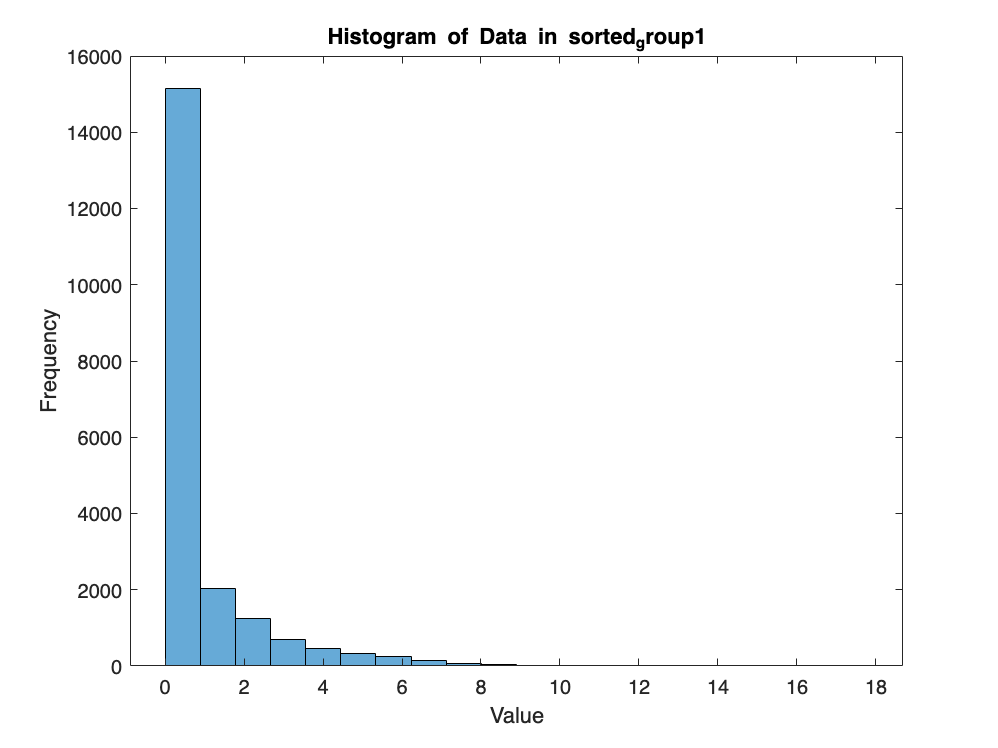

% For sorted_group1
figure;
histogram(sorted_group1(:), 20); % Adjust the number of bins as needed
title('Histogram of Data in sorted_group1');
xlabel('Value');
ylabel('Frequency');

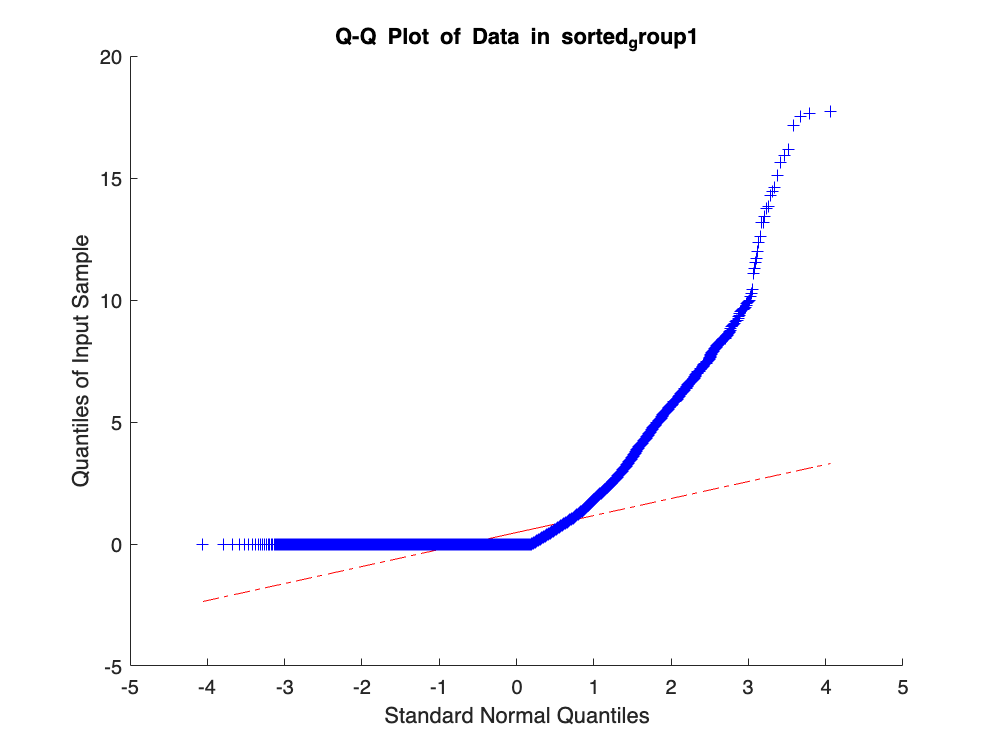


% For sorted_group1
figure;
qqplot(sorted_group1(:));
title('Q-Q Plot of Data in sorted_group1');

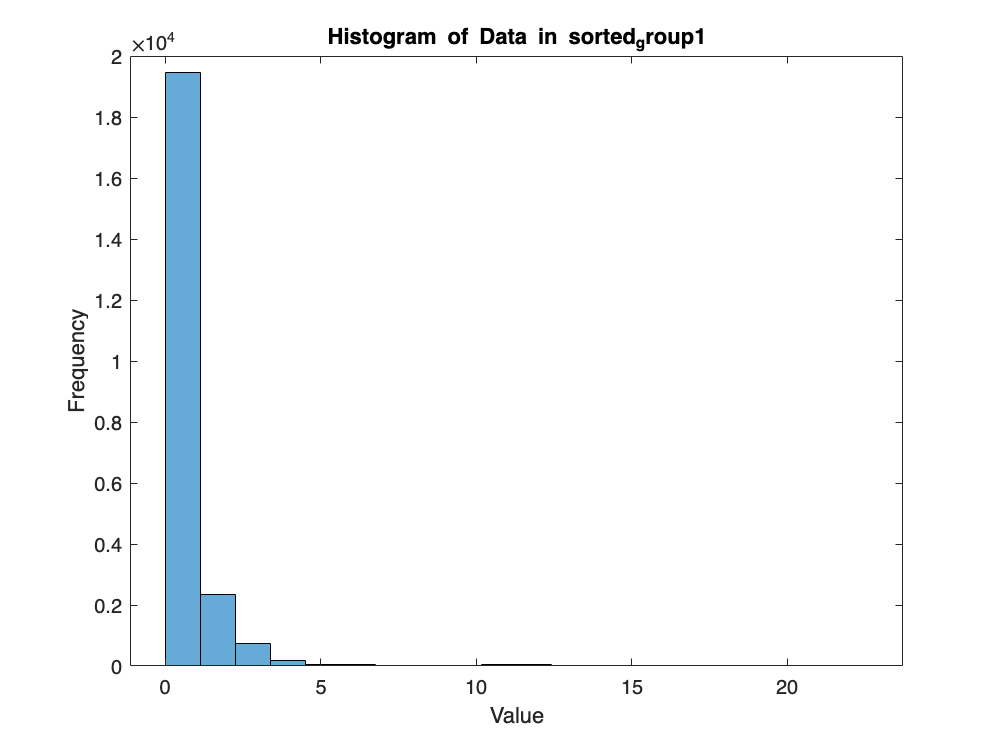

% For sorted_group1
figure;
histogram(sorted_group2(:), 20); % Adjust the number of bins as needed
title('Histogram of Data in sorted_group1');
xlabel('Value');
ylabel('Frequency');

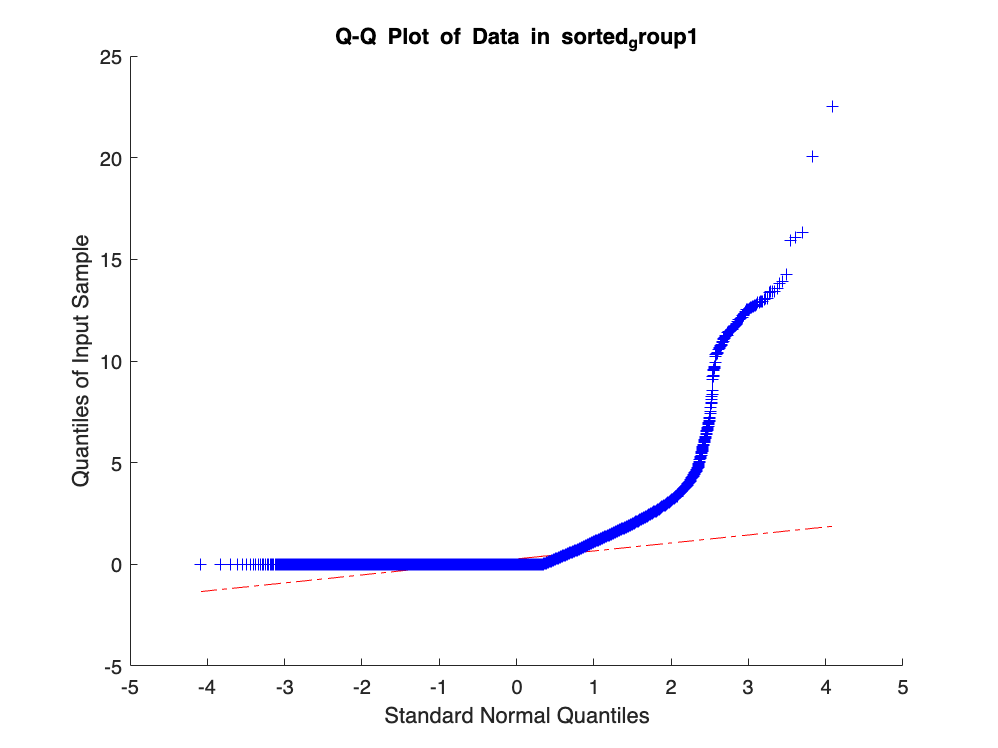


% For sorted_group1
figure;
qqplot(sorted_group2(:));
title('Q-Q Plot of Data in sorted_group1');

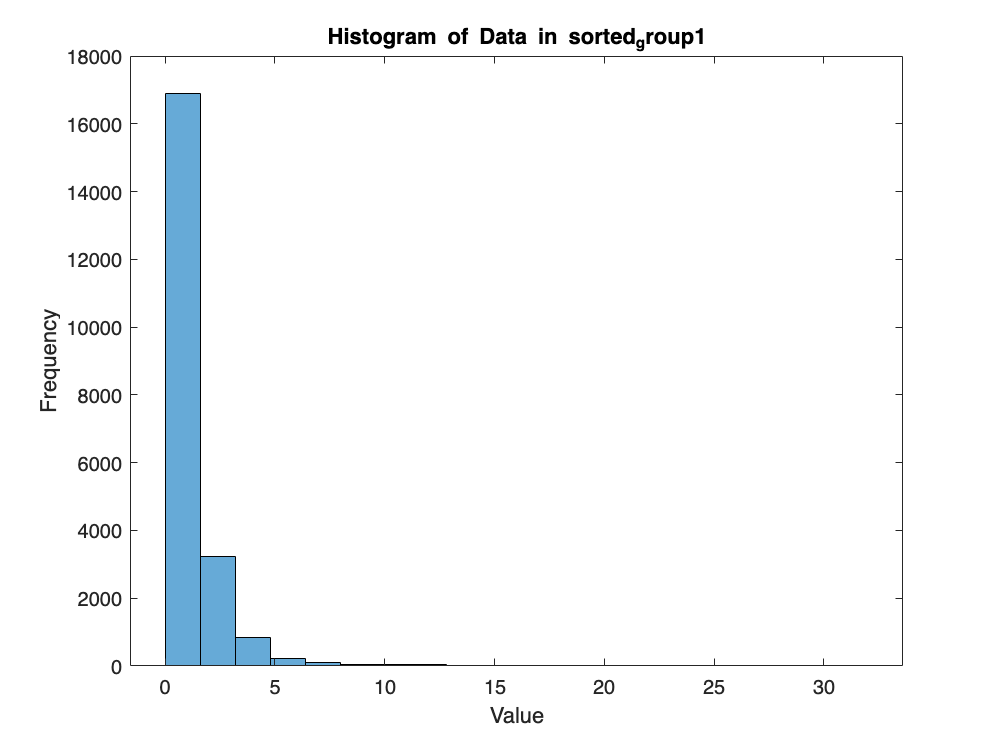

% For sorted_group1
figure;
histogram(sorted_group3(:), 20); % Adjust the number of bins as needed
title('Histogram of Data in sorted_group1');
xlabel('Value');
ylabel('Frequency');

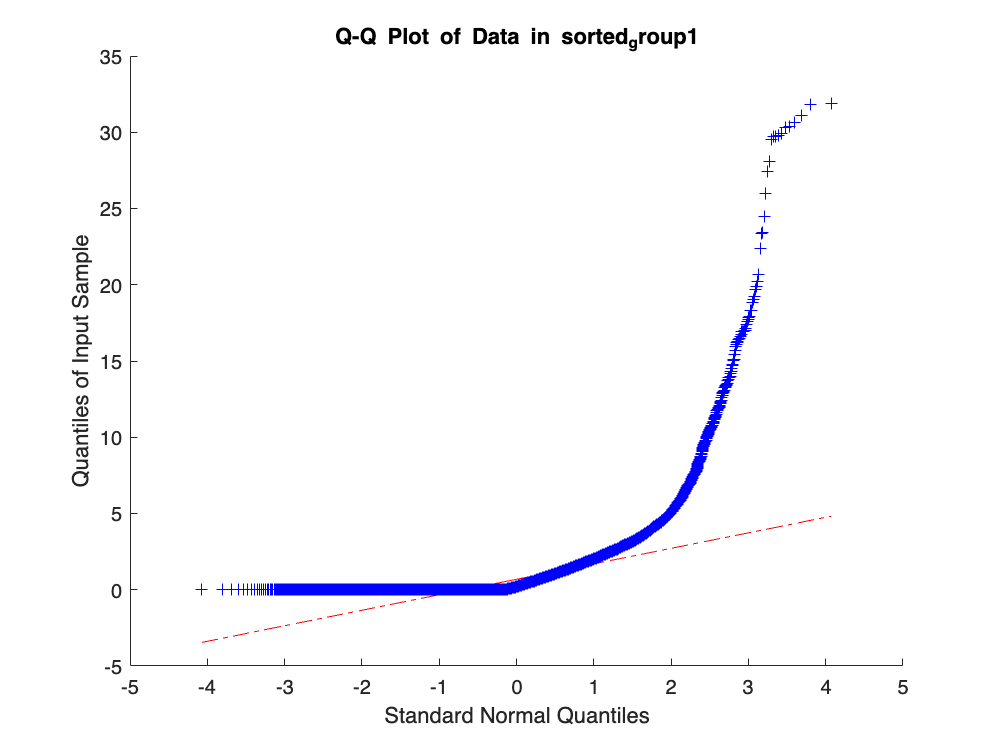


% For sorted_group1
figure;
qqplot(sorted_group3(:));
title('Q-Q Plot of Data in sorted_group1');



% Repeat the above steps for sorted_group2 and sorted_group3
% Repeat the above steps for sorted_group2 and sorted_group3

merge sorted data sets 

mergedData = [sorted_group1; sorted_group2; sorted_group3];


Plot the histogram 

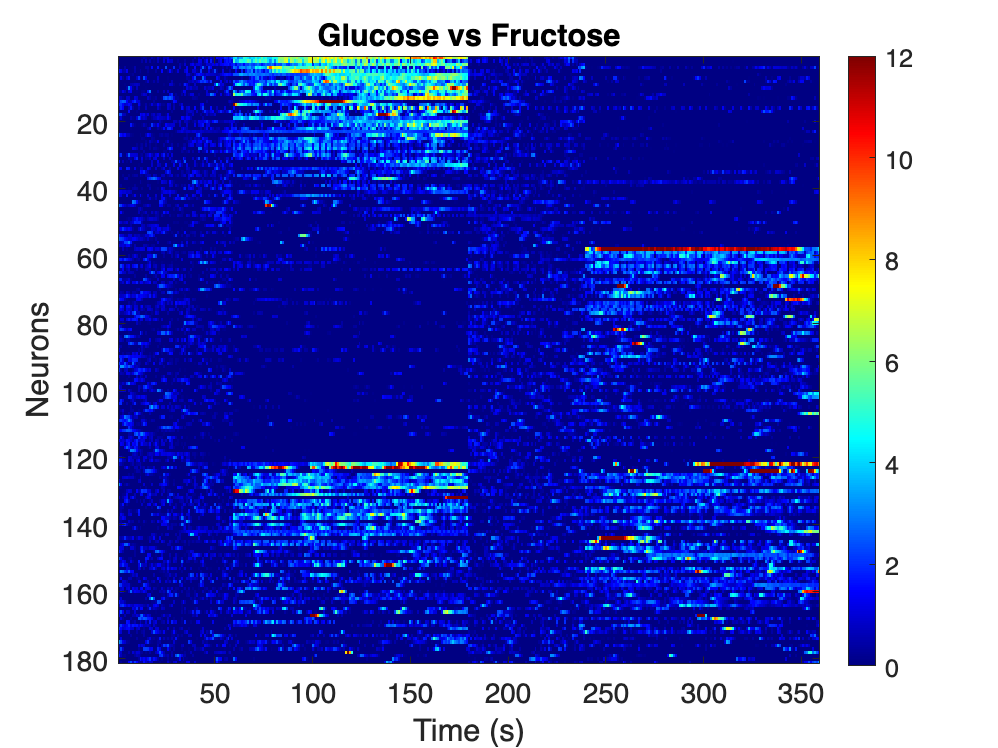

figure;
imagesc(mergedData);
colorbar;

hTitle =title('Glucose vs Fructose');
ylabel('Neurons');
xlabel('Time (s)');
set(gca, 'FontSize', 14);
% Adjust the font size for title, x-axis label, and y-axis label
set(hTitle, 'FontSize', 16);
% Add labels and titles
ylabel('Neurons');
xlabel('Time (s)');
set(gca, 'FontSize', 14);
% Adjust the color scale to highlight differences
caxis([0, max(mergedData(:))]);  % Set the color scale from 0 to the maximum z-score
% Display the name of the stimulus vertically along the white line

% Adjust the color scale to highlight differences
caxis([0, max(mergedData(:))]);  % Set the color scale from 0 to the maximum z-score
% Adjust the color scale to limit it to a maximum value of 20
caxis([0, 12]);

% Optionally, you can set a colormap for the heatmap
colormap('jet');  % You can choose a different colormap if desired

Plot line graphs 

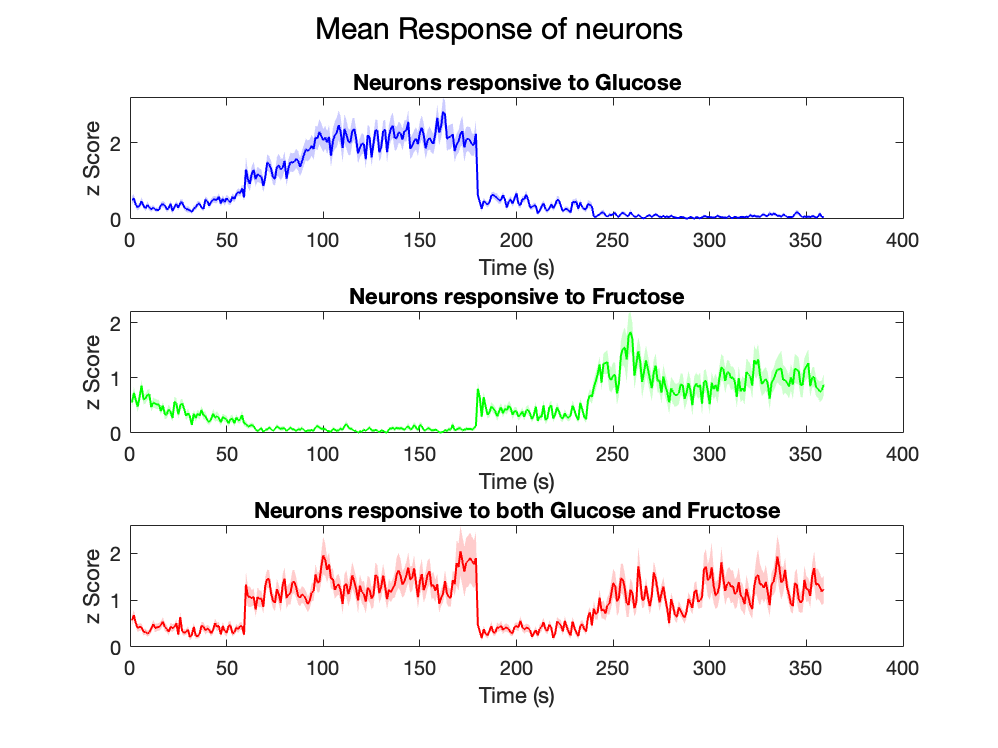

% Calculate the mean response across all neurons for each time point
mean_response_group1 = mean(sorted_group1, 1);
mean_response_group2 = mean(sorted_group2, 1);
mean_response_group3 = mean(sorted_group3, 1);

% Calculate the standard error for each group
std_error_group1 = std(sorted_group1) / sqrt(size(sorted_group1, 1));
std_error_group2 = std(sorted_group2) / sqrt(size(sorted_group2, 1));
std_error_group3 = std(sorted_group3) / sqrt(size(sorted_group3, 1));

% Create a figure
figure;
sgtitle('Mean Response of neurons')
% Plot the mean response with shaded standard error region for sorted_group1
subplot(3, 1, 1); % Create the first subplot
plot(1:size(mean_response_group1, 2), mean_response_group1, 'b', 'LineWidth', 1); % Adjust the 'LineWidth' value
hold on;
x1 = [1:size(mean_response_group1, 2), fliplr(1:size(mean_response_group1, 2))];
y1 = [mean_response_group1 + std_error_group1, fliplr(mean_response_group1 - std_error_group1)];
fill(x1, y1, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
title('Neurons responsive to Glucose');
xlabel('Time (s)');
ylabel('z Score');

% Plot the mean response with shaded standard error region for sorted_group2
subplot(3, 1, 2); % Create the second subplot
plot(1:size(mean_response_group2, 2), mean_response_group2, 'g', 'LineWidth', 1); % Adjust the 'LineWidth' value
hold on;
x2 = [1:size(mean_response_group2, 2), fliplr(1:size(mean_response_group2, 2))];
y2 = [mean_response_group2 + std_error_group2, fliplr(mean_response_group2 - std_error_group2)];
fill(x2, y2, 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
title('Neurons responsive to Fructose');
xlabel('Time (s)');
ylabel('z Score');

% Plot the mean response with shaded standard error region for sorted_group3
subplot(3, 1, 3); % Create the third subplot
plot(1:size(mean_response_group3, 2), mean_response_group3, 'r', 'LineWidth', 1); % Adjust the 'LineWidth' value
hold on;
x3 = [1:size(mean_response_group3, 2), fliplr(1:size(mean_response_group3, 2))];
y3 = [mean_response_group3 + std_error_group3, fliplr(mean_response_group3 - std_error_group3)];
fill(x3, y3, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
title('Neurons responsive to both Glucose and Fructose');
xlabel('Time (s)');
ylabel('z Score');

% 


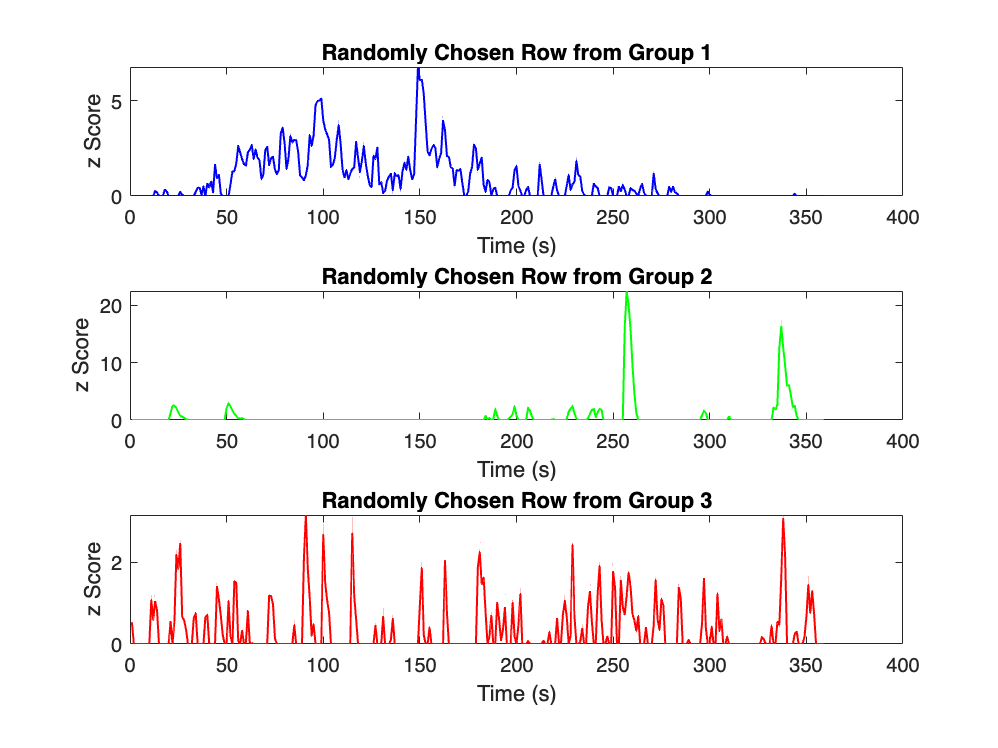

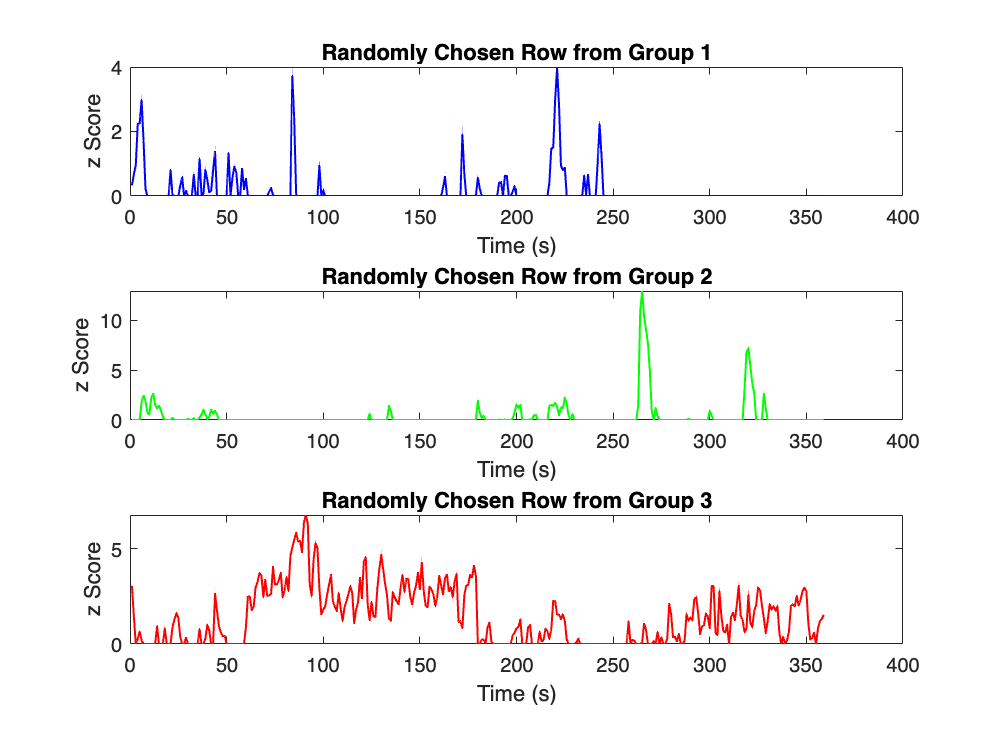

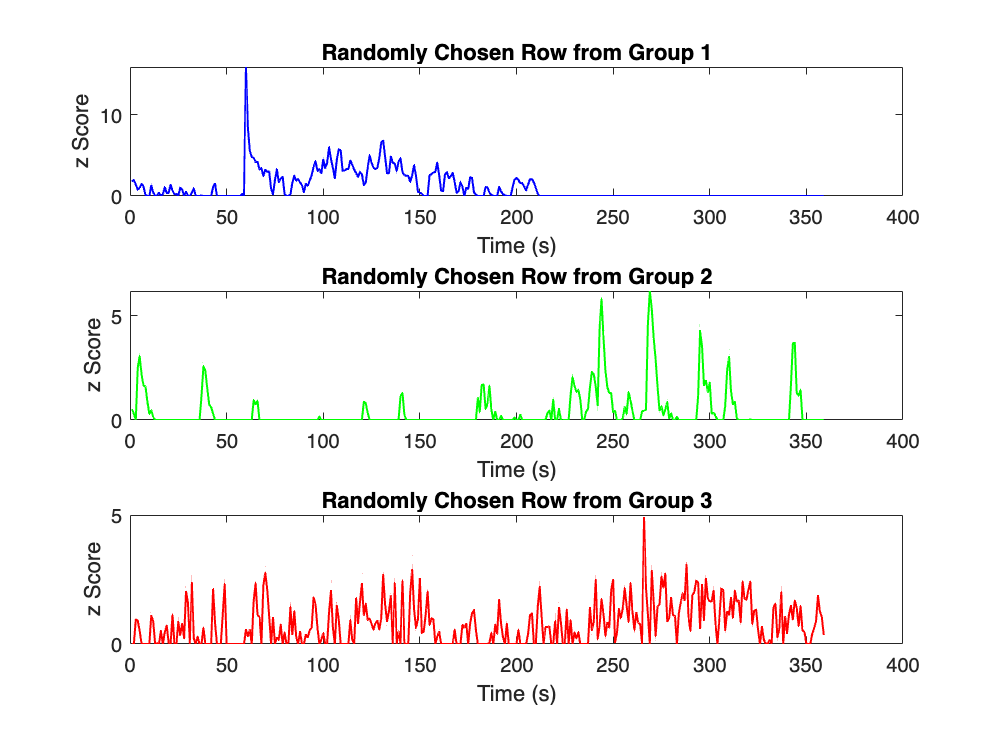

% Create new figures for randomly chosen rows in each group
for i = 1:3
    % Choose a random row index for each group
    random_row_index_group1 = randi(size(sorted_group1, 1));
    random_row_index_group2 = randi(size(sorted_group2, 1));
    random_row_index_group3 = randi(size(sorted_group3, 1));

    figure; % Create a new figure
    subplot(3, 1, 1);
    plot(1:size(sorted_group1, 2), sorted_group1(random_row_index_group1, :), 'b', 'LineWidth', 1);
    title('Randomly Chosen Row from Group 1');
    xlabel('Time (s)');
    ylabel('z Score');

    subplot(3, 1, 2);
    plot(1:size(sorted_group2, 2), sorted_group2(random_row_index_group2, :), 'g', 'LineWidth', 1);
    title('Randomly Chosen Row from Group 2');
    xlabel('Time (s)');
    ylabel('z Score');

    subplot(3, 1, 3);
    plot(1:size(sorted_group3, 2), sorted_group3(random_row_index_group3, :), 'r', 'LineWidth', 1);
    title('Randomly Chosen Row from Group 3');
    xlabel('Time (s)');
    ylabel('z Score');
end

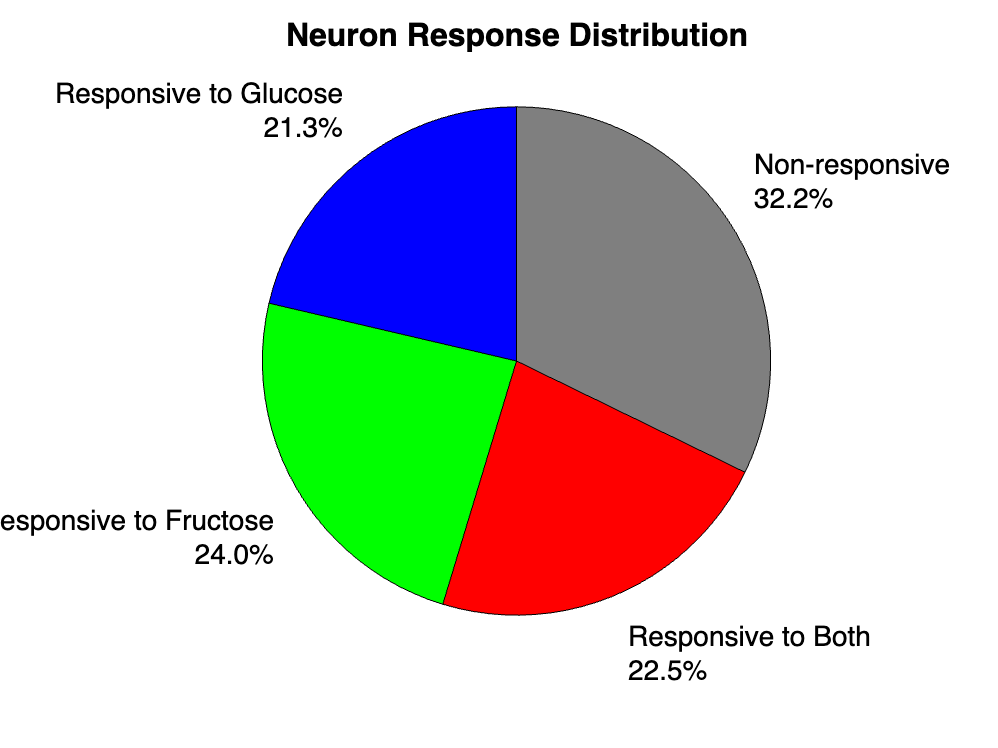

% Define the variables
totalNeurons = 267;  % Total number of neurons
responsiveToGlucose1 = size(sorted_group1, 1);  % Number of neurons responsive to glucose in sorted_group1
responsiveToGlucose2 = size(sorted_group2, 1);  % Number of neurons responsive to glucose in sorted_group2
responsiveToBoth = size(sorted_group3, 1);  % Number of neurons responsive to both stimuli

% Calculate the number of non-responsive neurons
nonResponsive = totalNeurons - (responsiveToGlucose1 + responsiveToGlucose2 + responsiveToBoth);

% Create a data vector for the pie chart
data = [responsiveToGlucose1, responsiveToGlucose2, responsiveToBoth, nonResponsive];

% Calculate percentages
percentages = 100 * data / totalNeurons;

% Create labels for the pie chart with percentages
labels = {
    sprintf('Responsive to Glucose\n%.1f%%', percentages(1)),
    sprintf('Responsive to Fructose\n%.1f%%', percentages(2)),
    sprintf('Responsive to Both\n%.1f%%', percentages(3)),
    sprintf('Non-responsive\n%.1f%%', percentages(4))
};

% Create a pie chart with custom colors and labels
figure;
h = pie(data, labels);

% Set colors using a colormap
colormap([0 0 1; 0 1 0; 1 0 0; 0.5 0.5 0.5]);  % Blue, Green, Red, Grey

pTitle= title('Neuron Response Distribution');
set(pTitle, 'FontSize', 16);
% Increase the font size of the labels
set(findobj(h, 'Type', 'text'), 'FontSize', 14);


% You can adjust the font size (here, it's set to 14) to your preferred size.


% Calculate the average scores for sorted_group1
average_glucose_scores_group1 = mean(sorted_group1(:, 60:180), 2);

% Calculate the average scores for sorted_group2
average_glucose_scores_group2 = mean(sorted_group2(:, 60:180), 2);

% Calculate the average scores for sorted_group3
average_glucose_scores_group3 = mean(sorted_group3(:, 60:180), 2);


mergedData_xaxis = [average_glucose_scores_group1; average_glucose_scores_group2; average_glucose_scores_group3];

% Now, you have three new variables: average_scores_group1, average_scores_group2, and average_scores_group3, each containing the averaged scores for each neuron.
% Calculate the average scores for sorted_group1
average_fructose_scores_group1 = mean(sorted_group1(:, 240:359), 2);

% Calculate the average scores for sorted_group2
average_fructose_scores_group2 = mean(sorted_group2(:, 240:359), 2);

% Calculate the average scores for sorted_group3
average_fructose_scores_group3 = mean(sorted_group3(:, 240:359), 2);

mergedData_yaxis = [average_fructose_scores_group1; average_fructose_scores_group2; average_fructose_scores_group3];

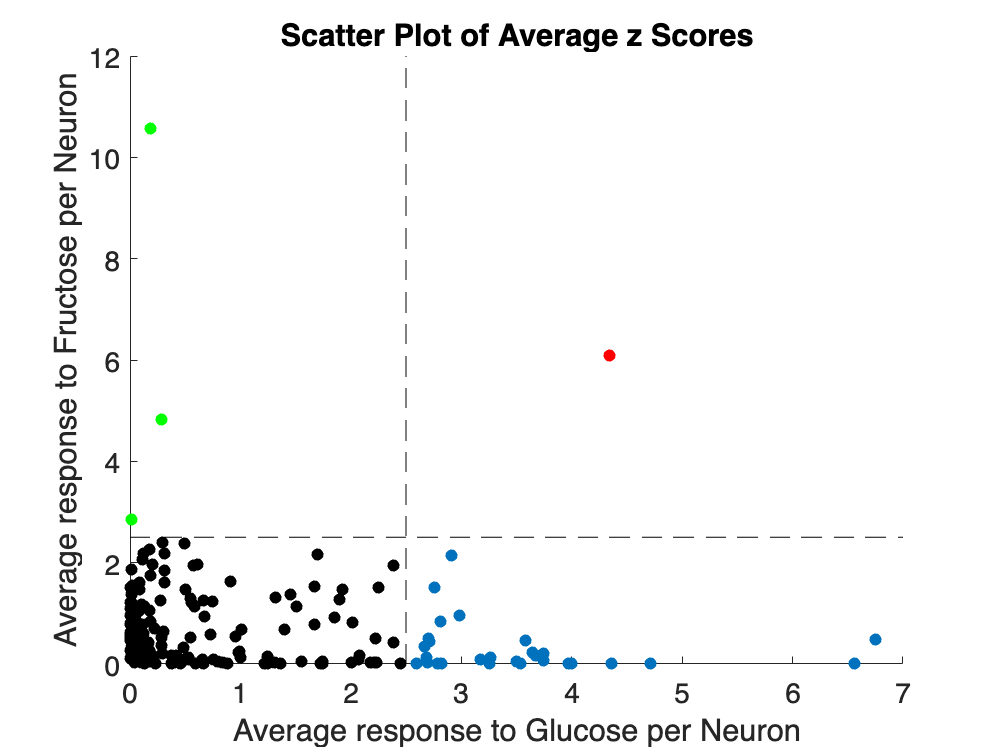

% Create a scatter plot
figure;
scatter(mergedData_xaxis, mergedData_yaxis, 'filled');
xlabel('Average response to Glucose per Neuron' );
ylabel('Average response to Fructose per Neuron');
title('Scatter Plot of Average z Scores');
set(gca, 'FontSize', 14);
hold on;
% Add vertical line at x = 2.5
xLine = 2.5;
yLimits = ylim;
plot([xLine, xLine], [yLimits(1), yLimits(2)], 'k--');
hold on;
% Add horizontal line at y = 2.5
yLine = 2.5;
xLimits = xlim;
plot([xLimits(1), xLimits(2)], [yLine, yLine], 'k--');

% Now, add color changes based on the specified conditions
greenPoints = mergedData_xaxis <= xLine & mergedData_yaxis >= yLine;
redPoints = mergedData_xaxis > xLine & mergedData_yaxis >= yLine;
greyPoints = mergedData_xaxis <= xLine & mergedData_yaxis < yLine;
hold on;  % Keep the previous plot

% Plot points to the left of the vertical line and above the horizontal line in green
scatter(mergedData_xaxis(greenPoints), mergedData_yaxis(greenPoints), 'g', 'filled');

% Plot points to the right of the vertical line and above the horizontal line in red
scatter(mergedData_xaxis(redPoints), mergedData_yaxis(redPoints), 'r', 'filled');

% Plot points to the left of the vertical line and below the horizontal line in grey
scatter(mergedData_xaxis(greyPoints), mergedData_yaxis(greyPoints), 'k', 'filled');


% The remaining points will remain blue

% The remaining points will remain blue

% Find the maximum values for sorted_group1
max_glucose_scores_group1 = max(sorted_group1(:, 60:180), [], 2);

% Find the maximum values for sorted_group2
max_glucose_scores_group2 = max(sorted_group2(:, 60:180), [], 2);

% Find the maximum values for sorted_group3
max_glucose_scores_group3 = max(sorted_group3(:, 60:180), [], 2);

% Combine the maximum values for all groups
mergedData_xaxis = [max_glucose_scores_group1; max_glucose_scores_group2; max_glucose_scores_group3];

% Find the maximum values for sorted_group1
max_fructose_scores_group1 = max(sorted_group1(:, 240:359), [], 2);

% Find the maximum values for sorted_group2
max_fructose_scores_group2 = max(sorted_group2(:, 240:359), [], 2);

% Find the maximum values for sorted_group3
max_fructose_scores_group3 = max(sorted_group3(:, 240:359), [], 2);

% Combine the maximum values for all groups
mergedData_yaxis = [max_fructose_scores_group1; max_fructose_scores_group2; max_fructose_scores_group3];

% Create a scatter plot
figure;
scatter(mergedData_xaxis, mergedData_yaxis, 'filled');
xlabel('Maximum response to Glucose per Neuron');
ylabel('Maximum response to Fructose per Neuron');
title('Scatter Plot of Maximum z Scores');
set(gca, 'FontSize', 14);
hold on;

% Add vertical line at x = 2.5
xLine = 2.5;
yLimits = ylim;
plot([xLine, xLine], [yLimits(1), yLimits(2)], 'k--');

% Add horizontal line at y = 2.5
yLine = 2.5;
xLimits = xlim;
plot([xLimits(1), xLimits(2)], [yLine, yLine], 'k--');

% Now, add color changes based on the specified conditions
greenPoints = mergedData_xaxis <= xLine & mergedData_yaxis >= yLine;
redPoints = mergedData_xaxis > xLine & mergedData_yaxis >= yLine;
greyPoints = mergedData_xaxis <= xLine & mergedData_yaxis < yLine;

hold on;

% Plot points to the left of the vertical line and above the horizontal line in green
scatter(mergedData_xaxis(greenPoints), mergedData_yaxis(greenPoints), 'g', 'filled');

% Plot points to the right of the vertical line and above the horizontal line in red
scatter(mergedData_xaxis(redPoints), mergedData_yaxis(redPoints), 'r', 'filled');

% Plot points to the left of the vertical line and below the horizontal line in grey
scatter(mergedData_xaxis(greyPoints), mergedData_yaxis(greyPoints), 'k', 'filled');


% The remaining points will remain blue
